D_0=[1.334,2.032,9.311,5.273,0.923,1.185,0.792,0.706,1.065,1.957,2.080,0.959].*1e-9;%无限扩散系数100

%溶液
U_T=0.0256;
Lj=0.0015;
for j=1:180
for i=1:3
V_sum1(i,1,j)=sum(z.^2.*C_clc(i,:,j).*D_0,2);
end
end
V_sum2=(fs*Id*Lj*U_T)/(V_sum1*F);
V_sol=sum(V_sum2,1);

%膜电阻
RA=4.9;
RB=5.44;
R_m=RA*2+RB; 
V_m=Id*R_m/1e4;
V_brane=ones(1,1,180)*V_m;

%膜电位
for j=1:180
P_i=(D_0.*conse_t(4,:,i))/Lj;
P_i2=(D_0.*conse_t(3,:,i))/Lj;
Cs_GOLD=C_clc(:,:,j);
for i=1:12
    if abs(z(1,i))~=1
        Cs_GOLD(1,i)=0;
        Cs_GOLD(2,i)=0;
        Cs_GOLD(3,i)=0;
    end
end
Cs_GOLD_c=zeros(3,12);
Cs_GOLD_a=zeros(3,12);
for i=1:12
    if z(1,i)>0
        Cs_GOLD_c(1,i)=Cs_GOLD(2,i);
        Cs_GOLD_c(2,i)=Cs_GOLD(3,i);
        Cs_GOLD_c(3,i)=Cs_GOLD(1,i);
    else
        Cs_GOLD_a(1,i)=Cs_GOLD(2,i);
        Cs_GOLD_a(2,i)=Cs_GOLD(3,i);
        Cs_GOLD_a(3,i)=Cs_GOLD(1,i);
    end
end

log1=log(sum(Cs_GOLD_c(1,:).*P_i+Cs_GOLD_a(2,:).*P_i,"all"));
log2=log(sum(Cs_GOLD_c(2,:).*P_i+Cs_GOLD_a(1,:).*P_i,"all"));
log3=log(sum(Cs_GOLD_c(3,:).*P_i2+Cs_GOLD_a(2,:).*P_i2,"all"));
log4=log(sum(Cs_GOLD_c(2,:).*P_i2+Cs_GOLD_a(3,:).*P_i2,"all"));
V_Gold(2,:,j)=(R*T*(log3-log4))/F;
V_Gold(1,:,j)=(R*T*(log1-log2))/F;
end
V_eme1=V_Gold(1,:,:);
V_eme2=V_Gold(2,:,:);

%双极膜
ph_a=-log10(C_clc(1,3,:)/1000);
ph_b=-log10(C_clc(2,3,:)/1000);
pH_diff=ph_b-ph_a;
V_BP=(2.3*R*T*pH_diff)/F;
V_BP(:,:,181)=[];


E_tot=[V_brane,V_sol,V_eme1,V_eme2,V_BP]*N;

1

ans = 1

Cca=(C_clc(3,7,1)-C_clc(3,7,:))*0.002*40/1000;
Ccat_=(C_clc(3,6,:)+C_clc(2,6,:)-C_clc(3,6,1)-C_clc(2,6,1))*0.002*61/1000

Ccat_ = Ccat_(:,:,1) =

     0


Ccat_(:,:,2) =

  -6.4648e-04


Ccat_(:,:,3) =

  -4.8435e-04


Ccat_(:,:,4) =

  -4.2955e-04


Ccat_(:,:,5) =

  -3.8208e-04


Ccat_(:,:,6) =

  -3.3728e-04


Ccat_(:,:,7) =

  -2.9304e-04


Ccat_(:,:,8) =

  -2.4885e-04


Ccat_(:,:,9) =

  -2.0457e-04


Ccat_(:,:,10) =

  -1.6016e-04


Ccat_(:,:,11) =

  -1.1566e-04


Ccat_(:,:,12) =

  -7.1048e-05


Ccat_(:,:,13) =

  -2.6325e-05


Ccat_(:,:,14) =

   1.8442e-05


Ccat_(:,:,15) =

   6.3303e-05


Ccat_(:,:,16) =

   1.0824e-04


Ccat_(:,:,17) =

   1.5321e-04


Ccat_(:,:,18) =

   1.9826e-04


Ccat_(:,:,19) =

   2.4332e-04


Ccat_(:,:,20) =

   2.8845e-04


Ccat_(:,:,21) =

   3.3359e-04


Ccat_(:,:,22) =

   3.7877e-04


Ccat_(:,:,23) =

   4.2396e-04


Ccat_(:,:,24) =

   4.6918e-04


Ccat_(:,:,25) =

   5.1440e-04


Ccat_(:,:,26) =

   5.5964e-04


Ccat_(:,:,27) =

   6.0487e-04


Ccat_(:,:,28) =

   6.5010e-04


Ccat_(:,:,29) =

   6.9533e-04


Ccat_(:,:,30) =

   7.4054e-04


Ccat_(:,:,31) =

 

for i=2:180
V_diff(1,:,i)=(E_tot(1,:,i)+E_tot(1,:,i-1))/2;
Ccaco3(1,1,i)=Cca(1,1,i)-Cca(1,1,i-1);
Ccat(1,1,i)=Ccat_(1,1,i)-Ccat_(1,1,i-1);
end
W_tot=E_tot*ic/60/1000;
Ccaco3_=repmat(Ccaco3,1,5);
Ccattot=repmat(Ccat,1,5);

W_ca=W_tot./Ccaco3_;
W_CO2=W_tot./Ccattot;
W_ca(1,:,1)=0;
W_CO2(1,:,1)=0;
%W_tab(1,:)=sum(W_ca,3)/180
%W_tab(2,:)=sum(W_CO2,3)/180
W_tot_=sum(W_tot,3);
W_tot_t=sum(W_tot_,"all");
msw=(0.002)*1015;
W_sw=W_tot_./msw;
sum(sum(W_sw,3)*1000)

ans = 5.3465

%W_tab(3,:)=sum(W_sw,3)/180
%W_tab=array2table(W_tab)

for i=1:180
Ctot(1,i)=(C_clc(2,6,i)+C_clc(3,6,i)-C_clc(2,6,1)-C_clc(3,6,1)+C_clc(2,5,i)+C_clc(3,5,i)-C_clc(2,5,1)-C_clc(3,5,1)+C_clc(3,7,1)-C_clc(3,7,i))*0.002;
des(1,i)=(sum(C_clc(:,12,i),1));
deca_(1,i)=(C_clc(3,7,1)-C_clc(3,7,i))*100/C_clc(3,7,1);
end
time=[1:180];
co2tot=Q_g*1000*0.1*60*time/22.4;
fix=(Ctot./co2tot)*100;
fix(end)

ans = 70.1644


deca=(C_clc(3,7,1)-C_clc(3,7,180))*100/C_clc(3,7,1)

deca = 92.3599



Qs=(Q_g*0.0025*1000*60*(time-1)/22.4);
ds=des*0.002./Qs*100

ds =        NaN   96.9033   97.0291   97.3230   97.5730   97.7750   97.9400   98.0774   98.1936   98.2930   98.3806   98.4573   98.5259   98.5877   98.6440   98.6947   98.7421   98.7854   98.8259   98.8634   98.8988   98.9318   98.9632   98.9926   99.0207   99.0473   99.0726   99.0968   99.1200   99.1422   99.1635   99.1839   99.2036   99.2226   99.2409   99.2586   99.2757   99.2923   99.3084   99.3239   99.3390   99.3537   99.3680   99.3818   99.3953   99.4085   99.4213   99.4338   99.4460   99.4579


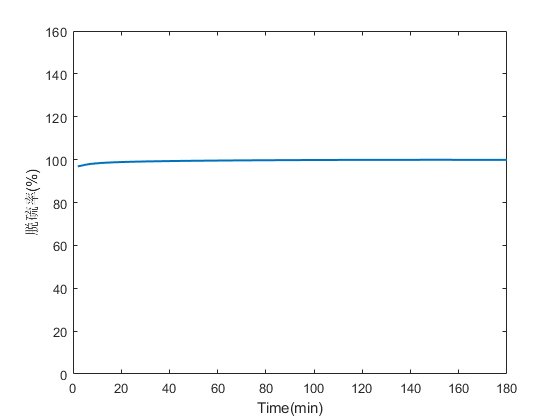


plot([1:180],ds,'LineWidth',1.5)
ylim([0 160]);
xlabel(['Time(min)']);
ylabel(['脱硫率(%)']);

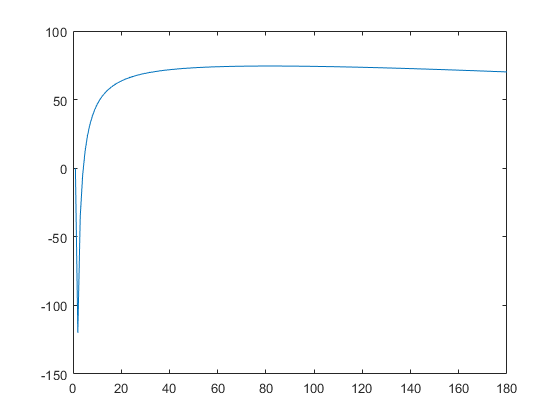

plot([1:180],fix)

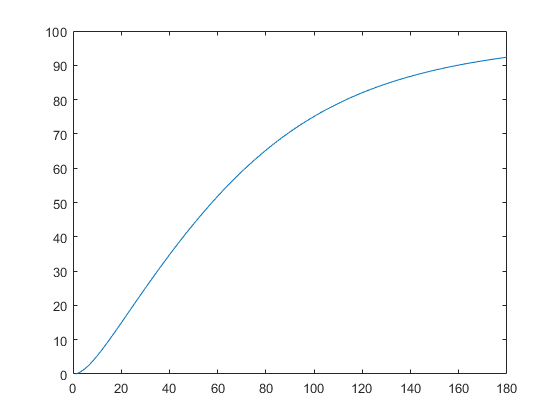

plot([1:180],deca_)

%plot([1:181],C_SO2)
